# **JacobiDS**

[Jacobi elliptic function ds](https://dlmf.nist.gov/22)

## Definition


$$\mathrm{ds}\left(x\left|m\right.\right)\equiv \frac{\textrm{dn}\left(x\left|m\right.\right)}{\mathrm{sn}\left(x\left|m\right.\right)}$$



$$\mathrm{ds}\left(x,k\right)\equiv \mathrm{ds}\left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, and dn and sn are Jacobi elliptic functions function.

Domain: $-\infty <x<\infty$, $-\infty <m<\infty$ i. For the specified domain, the  codomain *ds *is the set of real numbers.

Basic features:

$\mathrm{ds}\left(x+4K\left(m\right)\left|m\right.\right)=\mathrm{ds}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{ds}\left(-x\left|m\right.\right)=-\mathrm{ds}\left(x\left|m\right.\right)$ (odd)

Special values:


$$\mathrm{ds}\left(0\left|m\right.\right)=\infty$$


$\mathrm{ds}\left(x\left|0\right.\right)=1/\mathrm{sin}\;x$,  $\mathrm{ds}\left(x\left|1\right.\right)=\mathrm{csch}\;x$

Identities:


$$\textrm{ds}\left(x\left|m\right.\right)=\sqrt{m}\mathrm{cs}\left(x\sqrt{m}|m^{-1} \right)$$


## Syntax

Y = JacobiDS(X,K)

y = jds(x,k)

Y = mJacobiDS(X,M)

y = mjds(x,m)

## Description

Y = JacobiDS(X,K) returns the Jacobi elliptic function $\mathrm{ds}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **JacobiDS** is the wrapper function which calls the functions ***jds*** element-wise via the function **ufun2**.

y = jds(x,k) returns the Jacobi elliptic function $\mathrm{ds}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jds** calls the functions **sncndn **for calculation of$\mathrm{ds}\left(x,k\right)$ .

Y = mJacobiDS(X,M) returns the Jacobi elliptic function $\mathrm{ds}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mJacobiDS** is the wrapper function which calls the function **mjds** element-wise via the function **ufun2**.

y = mjds(x,m) returns the Jacobi elliptic function $\mathrm{ds}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.  **mjds** calls the functions **sncndn **for calculation of $\mathrm{ds}\left(x\left|m\right.\right)$ .

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

## **Numerical Examples**

**Salar input**

format long
k = 0.5; 
x = 0.5;
[jds(x,k), JacobiDS(x,k), mjds(x,k^2), mJacobiDS(x,k^2)]

ans =    2.044648050208716   2.044648050208716   2.044648050208716   2.044648050208716


Accuracy

fprintf('%.16g\n',jds(3,5))

-4.261876527884297


% Maple -4.261876527884310_65

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobidc.html)

disp(mJacobiDS([2 1 -3],[1 2 3]))

   0.275720564771783   0.462337524259901  -0.007917166052818



fprintf('%.16g\n',mjds(3,5))

32.03015460759671


% MATLAB 32.03015460759677_2037587224629884


Identities

x=2;
m = 0.12; % m > 0
disp(mjds(x,m)-sqrt(m)*mjcs(x*sqrt(m),1/m))

    -2.220446049250313e-16



**Vector input**

X=[1 2 3 4];
disp(JacobiDS(X,0)-1./sin(X))

     0     0     0     0



m = 0.12; 
disp(mJacobiDS(X,m)-sqrt(m)*mJacobiCS(X*sqrt(m),1/m))

   1.0e-14 *

  -0.022204460492503  -0.022204460492503  -0.799360577730113   0.022204460492503



**Matrix input**

X=[1 2; 3 4];
disp(JacobiDS(X,1)-1./sinh(X))

   1.0e-16 *

                   0   0.555111512312578
                   0  -0.069388939039072



M = [1 2; 0.2 0.3]; 
disp(mJacobiDS(X,M)-sqrt(M).*mJacobiCS(X.*sqrt(M),1./M))

   1.0e-15 *

                   0  -0.222044604925031
  -0.444089209850063                   0



## **Graphs **

**Example 1**

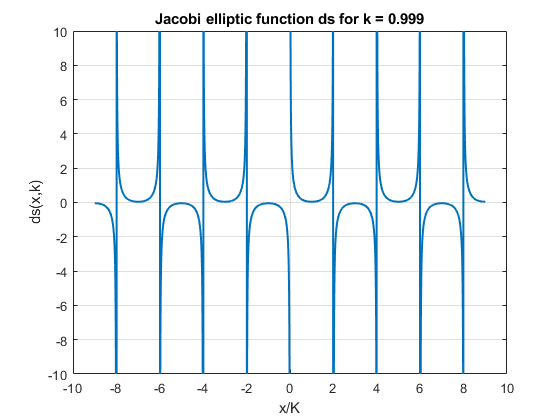

figure
x=-9:0.01:9;
k = 0.999;
K = elK(k);
plot(x,JacobiDS(x*K,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('ds(x,k)')
ylim([-10 10])
title(sprintf('Jacobi elliptic function ds for k = %g',k))
grid on

**Example 2**

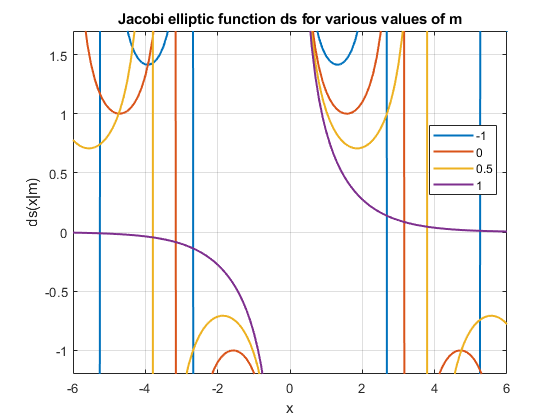

figure
X = -6:0.1:6;
M = [-1,0,0.5,1];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiDS(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.7])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Jacobi elliptic function ds for various values of m')
xlabel('x')
ylabel('ds(x|m)')

**Example 3**

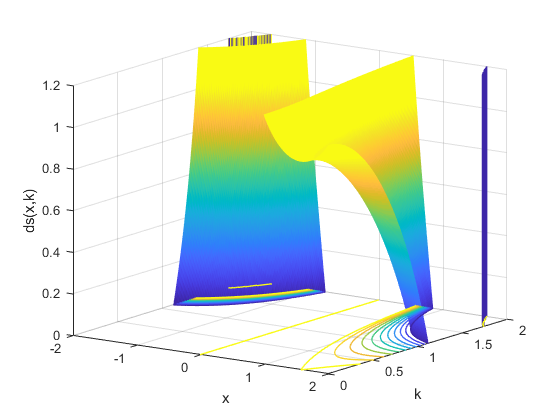

figure
x=-2:0.01:2;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiDS(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:1;
caxis([0 1])
view([35 15]);
xlabel('x')
ylabel('k')
zlabel('ds(x,k)')
zlim([0 1.2])
grid on

**Example 4**

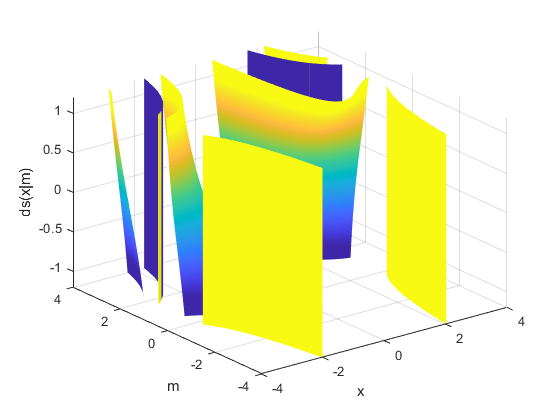

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(X,M,mJacobiDS(X,M),'EdgeColor','none')
view(3)
caxis([-1 1])
xlabel('x')
ylabel('m')
zlabel('ds(x|m)')
zlim([-1.2 1.2])
grid on

**Example 5**

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobidc.html)

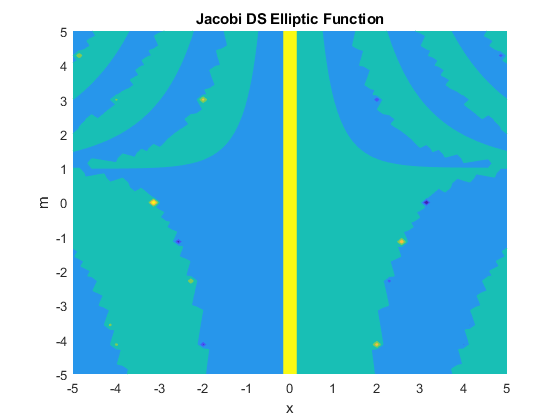

figure
f = @(x,m)mJacobiDS(x,m);
fcontour(f,'Fill','on') %,'LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi DS Elliptic Function')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also